Estimated area of triangle: 2.844


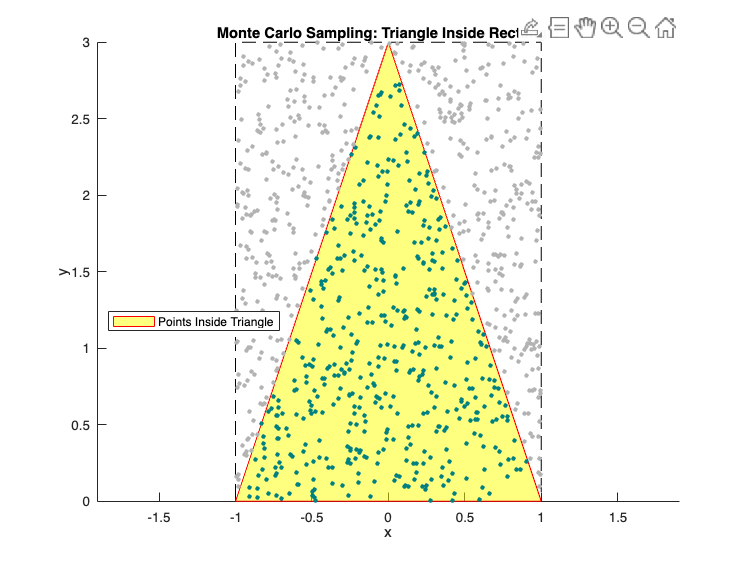

function MC_triangle()
    %define vertices
    v1 = [-1, 0]; 
    v2 = [1, 0];
    v3 = [0, 3];

    %setup for monte Carlo
    n = 1e3; %number of random points
    xmin = min([v1(1), v2(1), v3(1)]);
    xmax = max([v1(1), v2(1), v3(1)]);
    ymin = min([v1(2), v2(2), v3(2)]);
    ymax = max([v1(2), v2(2), v3(2)]);

    %generate random points inside rectangle
    rand_x = xmin + (xmax - xmin) * rand(1, n);
    rand_y = ymin + (ymax - ymin) * rand(1, n);

    %initialize counting variable
    inside_count = 0;

    %intitialize variables to store inside points
    inside_points_x = [];
    inside_points_y = [];
    outside_points_x = [];
    outside_points_y = [];

    %run for loop to check if each generated point is inside the triangle
    for i = 1:n
        %add to counter if point is inside triangle
        if is_inside_triangle([rand_x(i), rand_y(i)], v1, v2, v3)
            inside_count = inside_count + 1;

            %store the point for plotting later
            inside_points_x(end+1) = rand_x(i);
            inside_points_y(end+1) = rand_y(i);

        else
            %store point as outside
            outside_points_x(end+1) = rand_x(i);
            outside_points_y(end+1) = rand_y(i);

        end
    end

    %compute area of rectangle
    rect_area = (xmax - xmin) * (ymax - ymin);

    %compute area of triangle
    triangle_area = rect_area * (inside_count / n);

    %print result
    disp(['Estimated area of triangle: ', num2str(triangle_area)]);

    %plot the rectangle and triangle
    figure;
    hold on;
    
    %plot rectangle (bounding box)
    rectangle('Position', [xmin, ymin, xmax - xmin, ymax - ymin], 'EdgeColor', 'black', 'LineStyle', '--');
    
    %plot the triangle
    fill([v1(1), v2(1), v3(1)], [v1(2), v2(2), v3(2)], 'yellow', 'FaceAlpha', 0.5, 'EdgeColor', 'red');
    
    %plot points inside the triangle
    plot(inside_points_x, inside_points_y, '.', 'Color', [0, 0.5, 0.5], 'MarkerSize', 10);
    
    % Plot points outside the triangle
    plot(outside_points_x, outside_points_y, '.', 'Color', [0.7, 0.7, 0.7], 'MarkerSize', 10);

    %configure the plot
    axis equal;
    xlabel('x');
    ylabel('y');
    title('Monte Carlo Sampling: Triangle Inside Rectangle');
    legend({'Points Inside Triangle'}, 'Location', 'Best');
    hold off;


    %define functions
    function inside = is_inside_triangle(p, v1, v2, v3)
        %check if point is below each edge
        l1 = below_line(v1, v2, p);
        l2 = below_line(v2, v3, p);
        l3 = below_line(v3, v1, p);

        %define boolean "inside"-variable
        inside = l2 && l3 && ~l1;
    end

    function l = below_line(v1, v2, p)
        px = p(1);
        py = p(2);

        %check to avoid division by zero
        if abs(v2(1) - v1(1)) > 1e-15
            a = (v2(2) - v1(2)) / (v2(1) - v1(1));
        else
            a = 0;
        end

        %find b-value
        b = v1(2) - a * v1(1);

        %actually test if point is below line
        l = (py < a * px + b);
    end
end



MC_triangle()